# **SQUARE MAZE SOLVED USING Q-LEARNING**

**By Jonathan Sanz Carcelén**

**Contact: jonathan.sanz14@outlook.com**

**LinkedIn:**[ Jonathan Sanz Carcelén](http://www.linkedin.com/in/jonathan-sanz-carcelén-216a34198 )

## Introduction

The aim of this code is solving a randomly generated square maze (dimension $n$) using a $Q$-Learning algorithm involving an $\varepsilon$ greedy policy.

### Q-Learning Algorithm | Basic concepts

Reinforcement learning consists of a series of algorithms related to decision-making problems. The main elements are the ***agent***, which founds itself in a ***state*** $S_t$ of our ***environment*** and chooses an ***action*** $A_t$ that drives it to the next state $S_{t+1}$ obtaining a ***reward*** $R_{t+1}$. The aim of the algorithm is finding a ***policy*** that ***maximizes*** the total reward $R$. To choose which action $A_t$ is more beneficial (provides higher long-term reward), $Q$ ***values*** $Q\left(S_t ,A_t \right)$ are used. They quantify the expected future reward of taking action $A_t$ in state $S_t$. 

Note $Q$-Learning is an **off-policy method**, meaning that, knowing the $Q$ values, actions can be chosen only based on their $Q$ value, regardless of the policy being followed. Consequently, our goal will be obtaining accurate $Q$ values, and thereby defining an optimal policy of the problem. To do so, **Bellman Equation** is used. It is defined in an adaptative form as:


$$Q\left(S_t ,A_t \right)\gets Q\left(S_t ,A_t \right)+\alpha \cdot \left\lbrack \underset{\textrm{Objective}}{\underbrace{R_{t+1} +\gamma \cdot \max_a \;Q\left(S_{t+1} ,a\right)} } -\underset{\textrm{Estimation}}{\underbrace{Q\left(S_t ,A_t \right)} } \right\rbrack$$


Where $\alpha \;$is a parameter called the **learning rate**, quantifying the importance of the new estimation with respect to previous one ($\textrm{Objective}-\textrm{Predition}$). Note the $Q$ value associated to the next state $Q\left(S_{t+1} ,a\right)$ corresponds to the maximum $Q$ for any of the actions driving from $S_{t+1}$ to $S_{t+2}$. However, there is no requiriment on how to choose action $A_t$, between states $S_t$ to $S_{t+1}$ (needles to be the one with maximum $Q$). In our case, the $\varepsilon$ greedy** policy** will be followed (very common).

Finally, find attached an illustrative image of the $Q$-Learning algorithm. It was provided by a very instructive course on Reinforcement Learning (using Python) offered by Spain AI (Python y ML: De 0 a 100 con Reinforcement Learning). The following next link contians all the material provided on the course: [https://github.com/Matesanz/Reinforcement_Learning_Course](https://github.com/Matesanz/Reinforcement_Learning_Course).

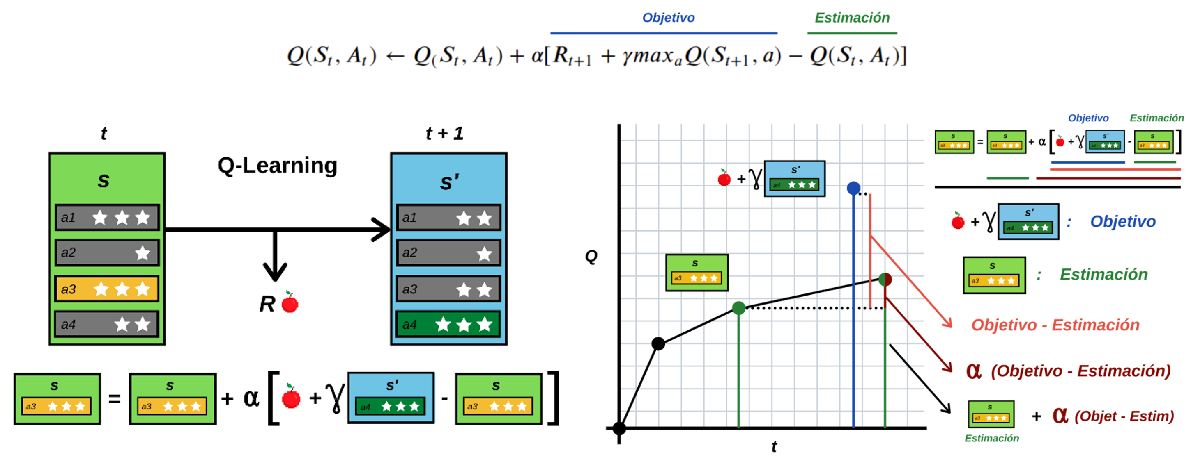

Figure 1. $Q$-Learning algorithm scheme

#### Balancing exploration and exploitation | Epsilon greedy** policy**

In Reinforcement Learning there is a discussion concerning on how to choose $A_t$. If the action with maximum $Q$ is always chosen, several apparently less optimal actions would be unexplored, obtianing a sub-optimal policy. Therefore, a balance between **exploitation** (use previous knowledge) and **exploration** (discover new options) must be found so as to take complete advantage of the algorithm and discovering the best policy. 

One option is implementing and $\varepsilon$ greedy policy. It consists of choosing action $A_t$ randomly an $\varepsilon \;%$ of the times, and the other $\left(1-\varepsilon \right)%$ of times, choosing such with highest $Q$, balancing exploration and exploitation. 

## Code description

### Input parameters | Build random square maze matrix

To generate the maze structure randomly, a certain dimension $n$, as well as the starting and ending states must be defined by the user:

clc, clear, home
%% Problem parameters chosen by the user:
% Square maze dimension
n = 12; 
% Start position
start_state = [1,1]; % row-column notation
start_state = sub2ind([n,n],start_state(1),start_state(2)); % Linear index notation
% End position
end_state = [n,n]; % row-column notation
end_state = sub2ind([n,n],end_state(1),end_state(2)); % Linear index notation

Then, a function called `build_maze` will provide a square $n$-matrix `maze` containing 4 different values: `wall_value`, `base_value`, `start_value`, end_value. Each one is used to distinguish whether that cell represents a wall or not, or if it is the starting or final node. These values have been introduced inside the function `build_maze` *manually* and have also been defined as an output of the function, since they will be used later in the code. Note the value itself is not what matters, it is just a way of providing a category for the cells. However, notice that `wall_value` should be a high negative number for better performance of the algorithm, since it will be used on the `reward` matrix (yet the quantity itself is meaningless in this case). Similarly, `base_value` must be much higher than `wall_value. `

The maze is randomly done, and the number of cell-walls has been set to `round(6*n)`, an arbitrary number that from experience seems to generate common solvable mazes of this sort. If for some reason, a non-solvable maze appears, just run the code again. Just in case, a solvable maze has been added to the code.

[maze,wall_value,base_value,start_value,end_value] = build_maze(n,start_state,end_state)

maze =      0  -500    -1    -1    -1    -1  -500  -500    -1  -500    -1    -1
    -1  -500    -1  -500    -1    -1    -1  -500    -1  -500  -500    -1
  -500    -1  -500    -1    -1    -1  -500    -1    -1  -500  -500    -1
  -500  -500    -1  -500    -1    -1  -500  -500  -500    -1    -1    -1
    -1  -500    -1    -1  -500    -1    -1    -1    -1  -500  -500    -1
  -500    -1  -500  -500  -500    -1    -1    -1    -1    -1    -1  -500
    -1  -500    -1    -1    -1  -500  -500    -1    -1    -1    -1    -1
    -1  -500    -1    -1    -1  -500  -500    -1    -1  -500    -1    -1
  -500  -500    -1  -500    -1    -1  -500    -1  -500  -500    -1    -1
  -500  -500  -500    -1  -500  -500    -1  -500    -1  -500    -1  -500


wall_value = -500

base_value = -1

start_value = 0

end_value = 100

### Build Reward Matrix

To model the maze-problem, a reward matrix (dimension $n^2 \;x\;n^2$) has been used (called `reward`). Rows represent all possible states $S_t$ (each state is understood as each of the cells of the maze matrix). Columns are the next possible states $S_{t+1}$. The value of element $\textrm{Reward}\left(i,j\right)$ is the reward $R_{t+1}$ of going from state $i$ to state $j$. If the actions are feasible, the reward is $+1$, otherwise it is $-\infty$. 

The assumed **feasible** **actions **are:

-     Up: $i\to i-n\;$

-     Down: $i\to i+n\;$

-     Left: $i\to i-1\;$

-     Right: $i\to i+1\;$

-     Diagonally SE: $i\to i+n+1\;$

-     Diagonally SW: $i\to i+n-1$

-     Diagonally NE: $i\to i-n+1\;$

-     Diagonally NW: $i\to i-n-1$

Where $i$ is the `maze`-matrix linear index corresponding to each state. 

 The function `build_reward_matrix` is in charge of this task. It basically overwrites on the `maze` matrix with a value of $-\infty$ unfeasible actions, regardless of the kind of state it may lead to (wall or not). However, since `maze` matrix was already defined with a given `wall_value`, those feasible actions leading to a wall-cell-state will present a low reward to prevent the agent to move there. In our case, a value of $-50$ was set to `wall_value` and $+1$ for non-wall states. 

Besides, to prevent the possibility of moving from a cell on the top to a cell on the bottom directly (since they are represented by consecutive states through linear indexing of matrices). This is, the following actions are also quantified with $-\infty$:

- States $1,n+1,2n+1$... cannot move up, NE or NW.

- States $n,2n,3n$ ... cannot move south, SE or SW.

Note there is another output `total_states.`

[reward,total_states] = build_reward_matrix(maze)

reward =   -Inf    -1  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -500  -500  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf
     0  -Inf  -500  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -500  -500    -1  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf
  -Inf    -1  -Inf  -500  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -500    -1  -500  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf
  -Inf  -Inf  -500  -Inf    -1  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf    

total_states = 144

### Q-Learning algorithm function

This function encodes the algorithm capable of building the $Q$-values matrix. It requires the previously discussed parameters: `gamma`, `alpha` and `epsilon` (to apply the $\varepsilon$ greedy policy). It consists of a for loop (the user can impose the maximum number of iterations, `maxIter`), and each loop-step represents an agent's trial of solving the maze, this is,** interacting **with the** environment**. Note $Q$-values are stored in a matrix `q` with the very same structure as the `reward` matrix.

The algorithm works as follows. Firstly, there is a general `for`**-loop** until reaching the maximum iterations allowed by `maxIter`. Each step of the `for`-loop can be understood as an attempt of the agent to solve the maze. Thus, it will always depart form the `start_state`. The goal at each attempt is reaching the `end_state`, so a `while`**-loop** is defined until this condition is met. Each step of the `while`-loop is, in fact, the process of moving from state $S_t$ to state $S_{t+1}$, and thereby updating the $Q$-value of action $A_t :S_t \to S_{t+1}$. The current state $S_t$ is denoted as `cs` and the next one $S_{t+1}$ as `ns`. A summary of the algorithm is:

      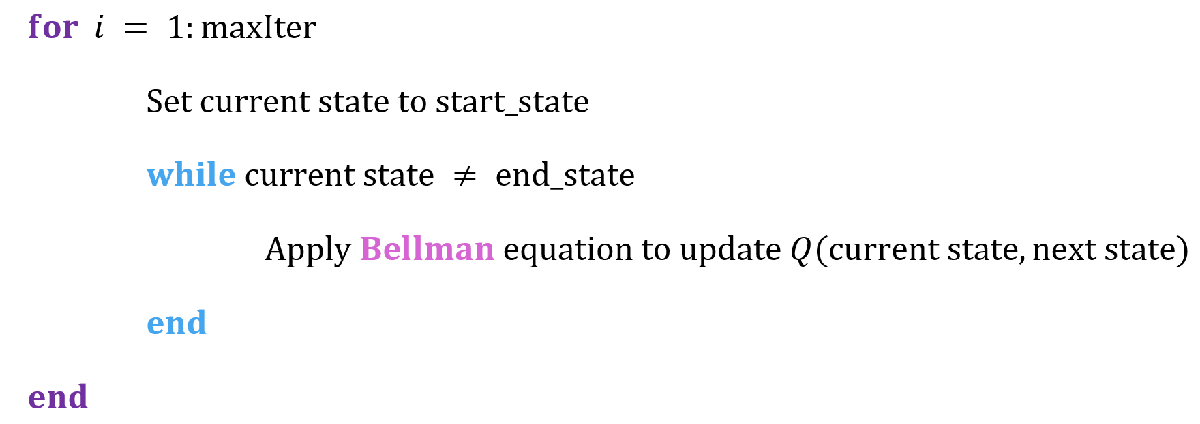

#### Updating Q-Values | Bellman equation

Every time the agent moves from `cs` to `ns`, Bellman equation is applied:


$$Q\left(S_t ,A_t \right)\gets Q\left(S_t ,A_t \right)+\alpha \cdot \left\lbrack R_{t+1} +\gamma \cdot \max_a \;Q\left(S_{t+1} ,a\right)-Q\left(S_t ,A_t \right)\right\rbrack$$


Firstly, the aim is selecting $A_t$, this is, one of the possible actions of `cs`. The set of all possible actions $A_t$ is noted as `nps`, and it is basically the columns of those cells in the `cs`-row of the `reward` matrix with a value higher than `wall_value` ($-\infty$ accounts for unfeasible actions). Among all these possibilities, one must be chosen through an $\varepsilon$ greedy policy. Thanks to the design of our `q` matrix, the value of the column coincides with the value of the next state `ns`. 

$\varepsilon$ greedy policy algorithm consists of an `if`-conditional depending on a value `x`, randomly chosen from a [0,1] uniform distribution. For the sake of simplicity, provided a value $x\in \left(\varepsilon ,1-\varepsilon \right)$, the agent will **exploit** the environment, this is, it will choose:


$$A_t \;\left|\;A_t ={\textrm{argmax}}_a \left\lbrack Q\left(S_t ,a\right)\right\rbrack \right.$$


Otherwise, it will **explore**, this is, choose randomly $A_t$. For this particular case, exploration was thought to be relevant, so the agent was additionally forced to always explore until a third of the total iterations `maxIter` was reached (exactly `round(maxIter/3)``)`. This part is encoded on function `choose_action_epsilon_greedy. `

Once `ns` is set, $Q\left(S_t ,A_t \right)$ and $R_{t+1}$ are straightforward: `q(cs,ns)` and `reward(cs,ns)` respectively. The remaining term before applying Bellman is $\max_a \;Q\left(S_{t+1} ,a\right)$, noted as `max_q`. It simply requires finding the set of all possible actions $A_{t+1}$, noted as `nps_2` (actions driving from state $S_{t+1}$ to $S_{t+2}$) and choosing the one with maximum $Q$.

Bellman equation in MATLAB language reads:

`q(cs,ns) = q(cs,ns) + alpha*(reward(cs,ns) + gamma*max_q - q(cs,ns))`

After checking that `cs`$\;\not= \;$`end_state, the agent moves to the new state ns` (impose `cs = ns` to update its value for the new iteration).  

%% Q-Learning algorithm
% Parameters
gamma = 0.9; % Importance of future rewards
alpha = 0.2; % Chosen from experience
maxIter = 1500; % Maximum iterations
epsilon = 0.5; % Balance exploration and exploitation
% Algorithm
[q] = Q_learning_algorithm(gamma,alpha,maxIter,start_state,end_state,wall_value,reward,epsilon)

q =    -1.1564  125.1202   -2.1860    0.7135    0.3493   -0.2710   -0.3519   -1.2760   -1.0922   -0.2351    1.5081    0.8586   -0.1576   -0.2322    1.0377   -1.0411   -1.7787   -0.7899    0.9295   -0.9035   -1.5031    0.2071    0.9916   -0.2494    0.1861   -1.2084   -0.4222   -0.6305   -0.0107   -0.4753   -0.1910    0.9130    0.2628   -2.0883    1.0598   -0.1860   -1.5840   -0.1812   -0.4862   -1.2760   -2.1729    0.3023   -0.9988    0.1122   -0.4590   -0.5219    0.4295    1.7018   -0.1038   -1.0034
  112.6082   -1.9488   -1.3270    0.3174   -0.7292   -0.9000    0.2695    0.6170   -0.2258    1.8773   -0.8889    0.1952   -1.3736    0.2870  140.1336   -0.8207   -0.9226    0.1616   -0.0904   -0.4959    0.9218   -0.4446    0.6035    0.4957    0.5766   -0.0654   -1.6509   -0.1184   -0.4505    1.6757   -0.0272   -1.1189    1.8542   -1.1750   -0.1981   -0.4209    0.5299    0.1146   -0.6839   -0.4163    1.3074   -0.7385   -0.3258    0.7055    0.5462    1.0049   -0.5856    0.7985   -1.7426   -2

### Finding the optimal path

Once the `q` matrix is found, by simply choosing the actions with higher $Q$-value the optimal path can be determined. Through function `solve_maze`, the vector `path` containing all the solution states is computed. The essence of this functions is a `while`-loop in which the agent moves from state to state maximizing the $Q$-values of each action. Note the chances of getting stuck in small loops have been omitted (up to order 4) by choosing then the second, third or fourth action with higher $Q$. The accuracy of the optimal path will reside on the accuracy of the $Q$-values. Since actions leading direclty to the `end_state` present a higher value than other actions (`end_value` > `base_value`), $Q$ of those actions will be valued higher, and subsequently expanding such *path optimality* hidden over the `q` matrix.

%% Solving the maze
[path,pmat,path_value] = solve_maze(maze,q,start_state,end_state)

path =      1
     2
    15
    28
    39
    52
    65
    78
    91
   104


pmat =     50     0     0     0     0     0     0     0     0     0     0     0
    50     0     0     0     0     0     0     0     0     0     0     0
     0    50     0    50     0     0     0     0     0     0     0     0
     0     0    50     0    50     0     0     0     0     0     0     0
     0     0     0     0     0    50     0     0     0     0     0     0
     0     0     0     0     0     0    50     0     0     0     0     0
     0     0     0     0     0     0     0    50     0     0     0     0
     0     0     0     0     0     0     0     0    50     0     0     0
     0     0     0     0     0     0     0    50     0     0     0     0
     0     0     0     0     0     0     0     0    50     0     0     0


path_value = 50

### Plotting results

The maze matrices have been graphically displayed through function `plot_maze_comparison`, involving `imagesc` function. Note a specific colormap has been developed, so as to make easier the modification of colour scales by the user. 

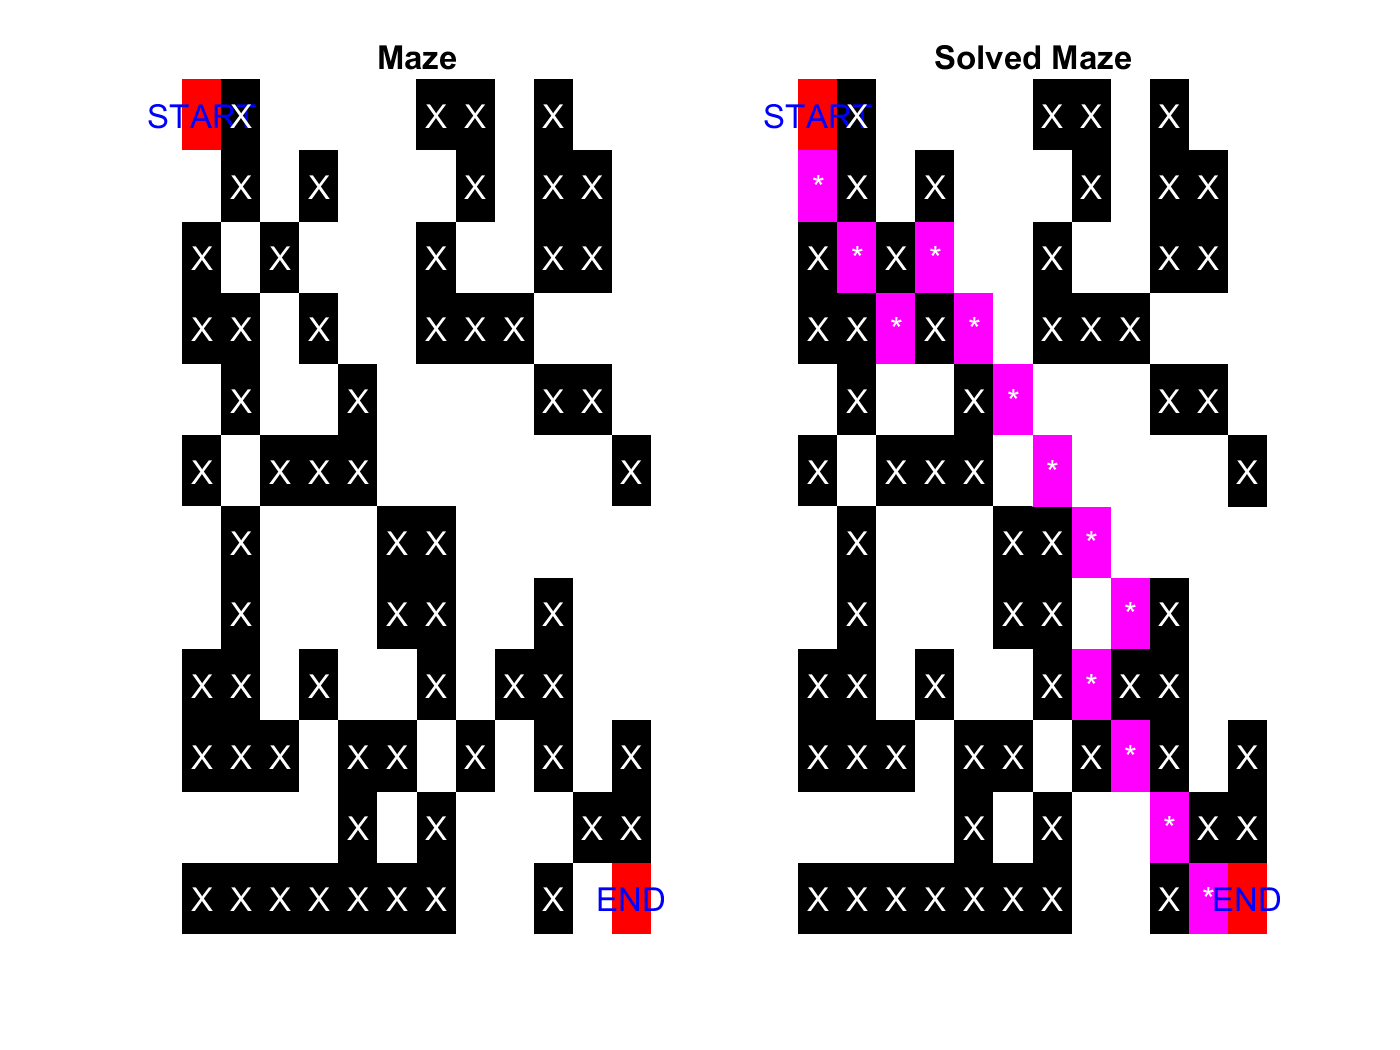

%% Plot results
plot_maze_comparison(maze,pmat,start_state,end_state,wall_value,base_value,start_value,end_value,path_value)

## Bibliography and acknowledgement

The structure of this code was inspired by:

- Bhartendu (2020). Q-learning-example ([https://github.com/matrixBT/Q-learning-example](https://github.com/matrixBT/Q-learning-example)), GitHub. Retrieved August 27, 2020.

- Spain AI (2020). Python y ML: De 0 a 100 con Reinforcement Learning ([https://github.com/Matesanz/Reinforcement_Learning_Course](https://github.com/Matesanz/Reinforcement_Learning_Course)), GitHub. Retrieved August 27, 2020.

While the aim of both codes is very similar, the present one tries to introduce new parameters and inputs so as to offer a better performance and higher versatility to the user. 